# **Matlab案例代码解析**

## 2. 典型绘图案例

### 2.7 知乎提问

#### 2.7.3 请问这种图是Matlab画出来的吗？

颜值即正义；

**颜色模板参考：**[**60套优雅的颜色模板**](https://zhuanlan.zhihu.com/p/444970597)

原问题：[https://www.zhihu.com/question/525638753/answer/2422123577](https://www.zhihu.com/question/525638753/answer/2422123577)

# 请问这种图是Matlab画出来的吗？

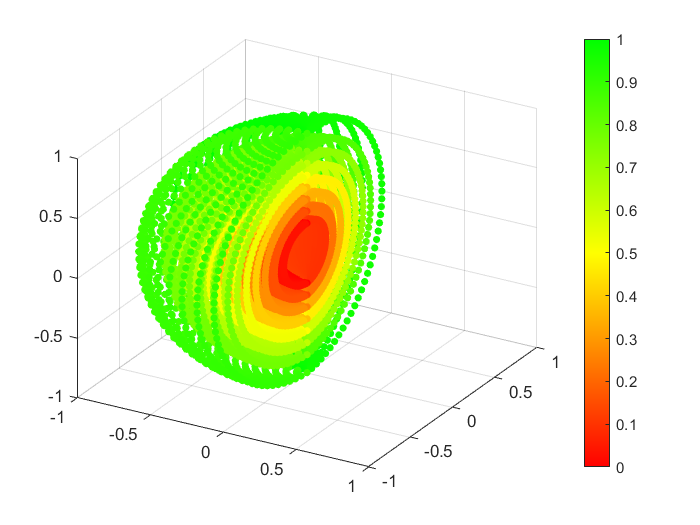

clear;clc;close all;
% 获取到颜色
[all_themes, all_colors] = GetColors();
[X,Y,Z] = sphere(50);
x = [0.25*X(:); 0.35*X(:); 0.45*X(:); 0.55*X(:); 0.65*X(:); 0.75*X(:); 0.85*X(:); X(:)];
y = [0.25*Y(:); 0.35*Y(:); 0.45*Y(:); 0.55*Y(:); 0.65*Y(:); 0.75*Y(:); 0.85*Y(:); Y(:)];
z = [0.25*Z(:); 0.35*Z(:); 0.45*Z(:); 0.55*Z(:); 0.65*Z(:); 0.75*Z(:); 0.85*Z(:); Z(:)];
x = x(:);
y = y(:);
z = z(:);
% 每个点都是等大的
s = 30;
% 颜色自定义：绿色 → 黄色 → 红色
colors = [[1, 0, 0]; [1, 1, 0]; [0, 1, 0]];
map = GenColormap(colors, length(x));
% 有一半不显示
z(x > 0) = nan;
h = scatter3(x, y, z, 19, map, 'filled');
xlim([-1, 1]);
colormap(map);
colorbar
% 视角
view(30, 30);